# AER1216 Project - Multi-rotor Range & Endurance

close all
clear all
clc

## Power Calculation

% Parameters
m = 0.420; % total mass of quadrotor in kg
g = 9.81; % in N/kg
C_D  = 0.97; % drag coefficient
S = 0.01; % reference area in m^2
rho_sea = 1.225; % air density at sea level in kg/m^3

% APC 8x6 Slow Flyer Properties
% https://m-selig.ae.illinois.edu/props/volume-1/data/apcsf_8x6_static_2783rd.txt
diam = 8 * 0.0254;  % diameter of a propeller in m

num_cells = 3;
battery_cap = 1500; % battery capacity in mAh
battery_vol = 3.7; % battery voltage in V; assumed from propulsion lecture slide 57

W = m * g; % total weight of quadrotor in N

A = 4 * (pi * (diam / 2)^2); % total area in m^2
P = sqrt(W^3 / (2 * rho_sea * A)); % power in W

E_b = num_cells * battery_vol * (battery_cap / 1000) * 3600; % bettery energy in J

eta_m = 0.7;
eta_e = 0.8;

% Find max range
V = 0:0.5:20;  % velocity array assumed from Assignment 3 from 0 to 20 m/s in increment of 0.5 m/s

D = 0.5 * rho_sea * (V.^2) * S * C_D;  % drag calculation at various veloities assuming AlphaD does not effect the Drag
alphaD = atan(D/W);
T = sqrt(W^2 + D.^2);

v = zeros(1, length(V));
P_ind = zeros(1, length(V));
P_tot = zeros(1, length(V));

for i = 1:length(V)
    % Solve 4th order polynomial for real, positive roots at each V 
    a4 = 1; % coefficient of v^4
    a3 = 2 * V(i) * sin(alphaD(i)); % coefficient of v^3;
    a2 = V(i)^2; % coefficient of v^2
    a1 = 0;
    a0 = -(W^2 + D(i)^2) / (2 * rho_sea * A); % use area of the 4 props

    v_all = roots([a4 a3 a2 a1 a0]);
    v(i) = v_all(real(v_all) > 0 & imag(v_all) == 0); % extracting the positive real roots 
    
    % Find P_ind and P_tot at each V and save the results
    P_ind(i) = T(i) * v(i);
    P_tot(i) = T(i) * (v(i) + V(i) * sin(alphaD(i))); 
end

## Endurance Calculation

% Endurance is maximized when Total Power is minimized
[min_P_tot, min_P_tot_idx] = min(P_tot);

t_e = (E_b * eta_m * eta_e)/min_P_tot/60; % s
sprintf('The max flight endurance is %.2f min.', t_e)

ans = 'The max flight endurance is 90.65 min.'

sprintf('The corresponding forward speed for max endurance is %.2f m/s', V(min_P_tot_idx))

ans = 'The corresponding forward speed for max endurance is 6.50 m/s'

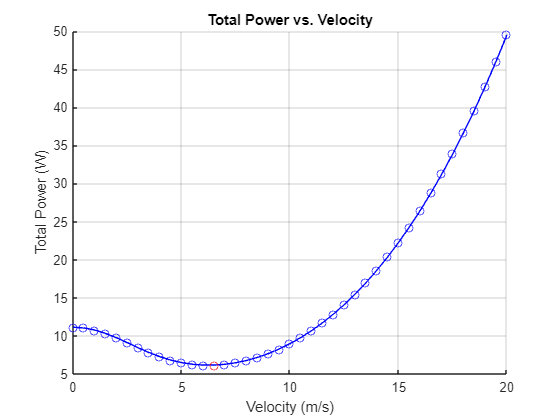

figure
hold on
plot(V, P_tot,'b-o')
plot(V(min_P_tot_idx), min_P_tot, 'r-o')
title('Total Power vs. Velocity')
xlabel('Velocity (m/s)')
ylabel('Total Power (W)')
grid on

## Range Calculation

% Range is maximized when Total Power / Velocity is minimized
[min_P_V, min_P_V_idx] = min(P_tot ./ V);

t_max_range = (E_b * eta_m * eta_e) / P_tot(min_P_V_idx);
max_range = t_max_range * V(min_P_V_idx) / 1000;

sprintf('The flight range is %.2f km', max_range)

ans = 'The flight range is 39.76 km'

sprintf('The corresponding forward speed for max range is %.2f m/s', V(min_P_V_idx))

ans = 'The corresponding forward speed for max range is 8.50 m/s'

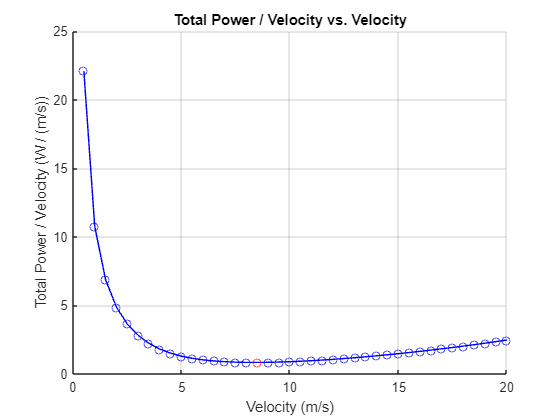

figure
hold on
plot(V, P_tot ./ V,'b-o')
plot(V(min_P_V_idx), P_tot(min_P_V_idx) ./ V(min_P_V_idx), 'r-o')
title('Total Power / Velocity vs. Velocity')
xlabel('Velocity (m/s)')
ylabel('Total Power / Velocity (W / (m/s))')
grid on

## Combined Plots

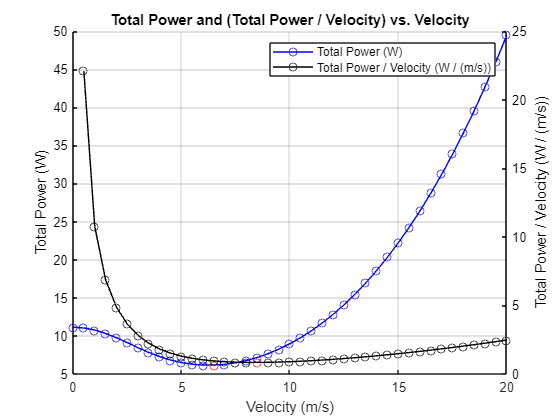

fig = figure;
set(fig,'defaultAxesColorOrder',[[0 0 0]; [0 0 0]]);
hold on

yyaxis left
plot(V, P_tot,'b-o')
plot(V(min_P_tot_idx), min_P_tot, 'r-o')
ylabel('Total Power (W)')

yyaxis right
plot(V, P_tot ./ V,'k-o')
plot(V(min_P_V_idx), P_tot(min_P_V_idx) ./ V(min_P_V_idx), 'r-o')
ylabel('Total Power / Velocity (W / (m/s))')

title('Total Power and (Total Power / Velocity) vs. Velocity')
xlabel('Velocity (m/s)')
legend('Total Power (W)', '', 'Total Power / Velocity (W / (m/s))', '')
grid on